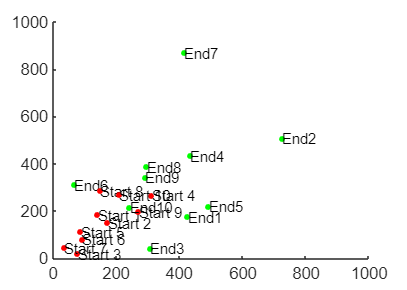

clc;
clear;
rng(123)
%Import Parameters
[waypointSizing,dt,KaE,Kv,xrange,yrange,ArrivalDist,spacing,Kd,Ke,fontsz] = setParam();

%Number of Drones
n = 10;

%Generate contour plots or not
ShowContours = false;

%Initiate drones
Drones = droneInitiate(n);

%START OF WHILE LOOP
%Show drones (AGENT 'SEES' DRONE POSITIONS)
showDrones('DronesStart',Drones,waypointSizing,xrange,yrange,fontsz);

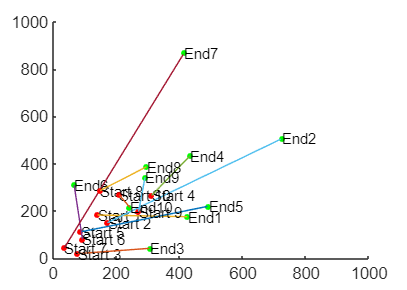



%temporary contour plot returns the reward for each drone at that position
[ContourPlot, Reward] = RewardContour(Drones,xrange,yrange,spacing,Kd,Ke,waypointSizing,ShowContours,fontsz);

%Agent ACTS by chosing KaE
terminate = false;
while terminate == false
[Drones,terminate] = Update(Drones,KaE,Kv,ArrivalDist,dt);
end
%agent Looks at reward and compares it to predicted  from value funtion
%agent improves policy
%END OF WHILE LOOP


%End look atr trajectory to then determine how well the agent did for each
%drone
showDrones('Drones End',Drones,waypointSizing,xrange,yrange,fontsz);